# 1ING09-Digital Signal Processing

## Laboratory 1A (Guided)

#### Topics:

- Introduction to sampling process (Sampling Frequency, Sampling Period)

- Introduction to elementary discrete-time signals (unit impulse, unit step, discrete-time sinusoidal functions)

- Introduction to discrete-time systems and its properties (linearity, time-invariance, causality and BIBO stability)

#### **Objectives:**

- **Provides an introduction to MATLAB as a programming tool for digital signal processing**

- **Gain insights from graphic-visualization of biomedical signals according to its inherent characteristics **

- **Learn to implement discrete-time signals and systems in MATLAB from their analytical expressions **

### **QUESTION 1 - Phonocardiogram Signal (3 p) **

A recording corresponding to a database of heart fetal sounds is stored in the file `PCG_fetal.wav`. This phonocardiogram (PCG) signal was recorded by a digital stethoscope. Analyze the provided PCG signal in the time-domain and obtain its graphical representation.

a) **(0.25 p)** Use the `audioread()` function and store the PCG signal and its corresponding sampling frequency in a pair of variables (see the MATLAB documentation)

**NOTE: **Since the PCG signal has been recorded in an audio format, it contains two channels of data (left and right). Consider a single channel (any of them).

[y,Fs] = audioread('PCG_fetal.wav');
size(y)

ans =      1451760           2


y =y';
size(y)

ans =            2     1451760


left_channel = y(1,:);
right_channel = y(2,:);
%voy a usar el canal derecho

b) **(0.25 p)** What's the sampling frequency used by the digital stethoscope? Express it in `kHz (kiloHertz)` units

display(['The sampling frequency (kHz) = ',num2str(Fs*10^(-3)), ' kHz '])

The sampling frequency (kHz) = 16 kHz 


c) **(0.25 p) **What's the sampling period of the recording? Express it in `us (microseconds)` units

display(['The sampling period of the recording (us) = ',num2str(1/(Fs*10^(-3))), ' us '])

The sampling period of the recording (us) = 0.0625 us 


d) **(0.25 p) **What's the time duration of the recording? Express it in `s (seconds)` units

%necesito el número de muestreo, por lo que uso size
N= size(y,2);
time_duration = (N-1)*(1/Fs)

time_duration = 90.7349

display(['The time duration of the recording (s) = ',num2str(time_duration), ' s '])

The time duration of the recording (s) = 90.7349 s 


e) **(1 p) **Plot the PCG signal by using the `plot()` function. Customize it by setting `xlabel(), ylabel(), xlim(), ylim(), title() `properly

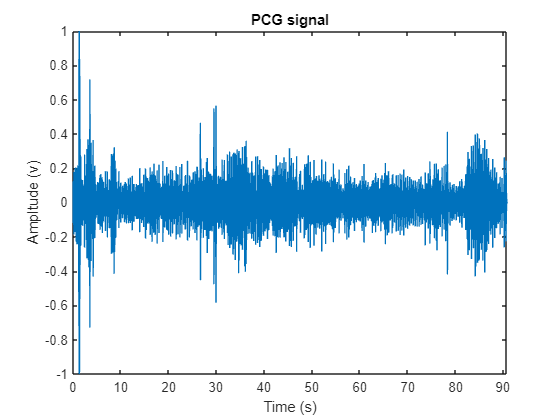

%primero necesito tener el tiempo
N = size(right_channel,2);
n = 1:N;
Ts = 1/Fs;
Tiempo = (n-1)*Ts;
figure();
plot(Tiempo,right_channel)
title('PCG signal')
xlabel('Time (s)')
ylabel('Ampltude (v)')
xlim([0 time_duration])
ylim([-1 1])

f) **(0.5 p) **Can you recognize some pattern in the plotted signal? What if you consider an small inspection window (short-time duration)? Ensure a suitable time-duration for the selected window and provide a plot of the PCG signal on that interval.

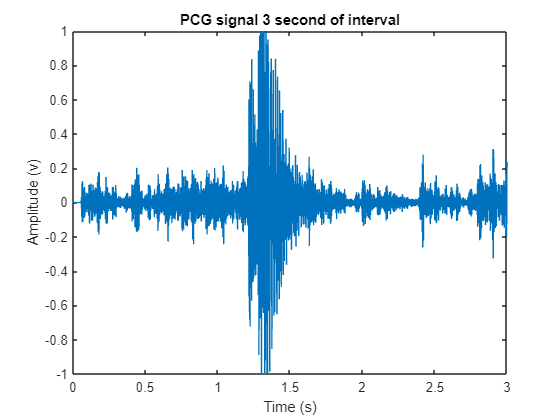

% Con el ploteo hecho en el anterior inciso no logro reconocer un patron,
% ya que todo esta muy junto y no se aprecia nada con precisión. EN el caso
% que considera una ventana más pequeña como por ejemplo de 2 segundo, creo
% que se podría observar un patrón.
time_duration_interval = 3 ;% defino de cuanto tiempo va ser el intervalo que voy a usar
sample = time_duration_interval*Fs; % el numero de muestreo que hay en esos 2 segundo
sample_end = min(sample,N);% lo que busco con esto es que el limite final de mi ventana sea el menor posible
%ahora necesito tener mi vector tiempo
n = 1: sample_end;
Ts = (n-1)*(1/Fs); % mi vector tiempo  en segundos
% ahora necesito la la señal en ese intervalo
signal = right_channel(1:sample_end);

figure();
plot(Ts,signal)
title('PCG signal 3 second of interval')
xlabel('Time (s)')
ylabel('Amplitude (v)')

g) **(0.5 p) **Answer the following questions based on your results from item d)  

- **(0.25 p) **Can you find the hear-beat in beats-per-minute (BPM) of the fetous?

% fisrt i need to find the peaks of the channel
time_duration_interval = 10 ;% define how much time are gonna use
sample = time_duration_interval*Fs; % the number of samples in 10 seconds
sample_end = min(sample,N);% i search with this the final limit
%now i need my vector time
n = 1: sample_end;
Ts = (n-1)*(1/Fs); 
% now i need the signal in that interval
signal = right_channel(1:sample_end);
[pks,locs] = findpeaks(signal); %search the peaks in this signal
%count the peaks
num_beats = length(pks);
%divide to have minutes
total_minutes = time_duration / 60;


BPM = num_beats / time_duration % this is the bpm

BPM = 144.5750

- **(0.25 p) **Regarding with the obtained BPM. Does it corresponds with typical or pathological BPM fetous values? 

%this is a typical BPM fetous values, because the ragne is from 120 to 160
%BPM, so is in the range.

### **QUESTION 2 - Elementary Discrete-Time Signals (2.5 p) **

**NOTE: **Elementary sequences such as u*nit impulse, unit step, discrete-time sinusoidal and discrete-time complex exponential* are inifinite sequences by definition. 

- **Unit Impulse**

              
$$\delta \;\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1 & n=0\\
0 & n\;\not= \;0
\end{array}\right.$$


- **Unit Step**

              
$$u\;\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1 & n\ge 0\\
0 & n<\;0
\end{array}\right.$$


- **Discrete-time sinusoidal**

              
$$\begin{array}{l}
x_1 \;\left\lbrack n\right\rbrack =A_1 \cdot \sin \left(\omega_1 n+\phi_1 \;\right)\\
x_2 \;\left\lbrack n\right\rbrack =A_2 \cdot \cos \left(\omega_2 n+\phi_2 \;\right)
\end{array}$$


- **Discrete-time complex exponential**

              
$$x\;\left\lbrack n\right\rbrack =A\cdot e^{j\left(\omega n+\phi \;\right)} =A\cdot \left\lbrack \cos \left(\omega n+\phi \;\right)+j\ldotp \sin \left(\omega n+\phi \;\right)\right\rbrack$$


However, it's only possible to represent finite sequences in MATLAB. For this reason, a particular interval (a set of values for $n$, where $n$ is the independent variable) must be considered for representing these signals.

*Example:* Consider the definition inverval given by: $n\in \left\lbrack -10,10\right\rbrack$. Implement a finite u*nit impulse*

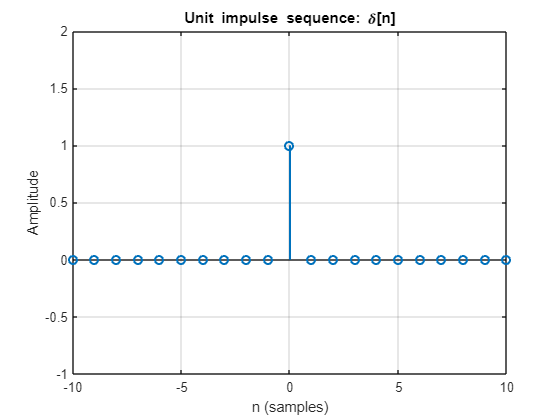

n = -10:10;
unit_imp = (n == 0);

figure;
stem(n,unit_imp, 'Linewidth',1.5)
title('Unit impulse sequence: \delta[n]')
xlabel('n (samples)');
xlim([-10 10]);
ylabel('Amplitude');
ylim([-1 2]);
grid on;

An **scaled and shifted Unit Impulse** can be expressed as:

              
$$\begin{array}{l}
x\left\lbrack n\right\rbrack \;=\;A\cdot \delta \;\left\lbrack n-k\right\rbrack =\left\lbrace \begin{array}{ll}
A & n=k\\
0 & n\;\not= k
\end{array}\;\;,\;\textrm{where}:\;\;\right.\\
\;\\
A:\;\textrm{scaling}\;\textrm{factor}\;\left(A\in \Re \right)\;\\
k:\textrm{time}-\textrm{shifting}
\end{array}$$


a) **(0.5 p)** Implement the following two sequences:

a.1) **(0.25 p)**

- 
$$x_{1\;} \left\lbrack n\right\rbrack \;=\;3\cdot \delta \;\left\lbrack n-2\right\rbrack ,\;\;n\in \left\lbrack -1,7\right\rbrack$$
   

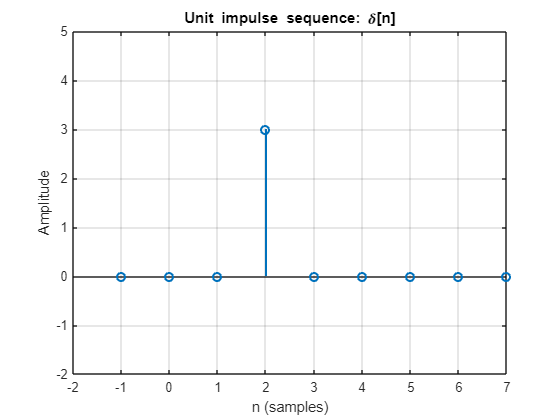

n = -1:7;
unit_impulse= 3*(n==2);
figure();
stem(n,unit_impulse,'linewidth',1.5)
title('Unit impulse sequence: \delta[n]')
xlabel('n (samples)')
ylabel('Amplitude')
xlim([-2 7])
ylim([-2 5])
grid on

a.2) **(0.25 p)**

-  **(0.25 p) **$x_{2\;} \left\lbrack n\right\rbrack \;=-2\cdot \delta \;\left\lbrack n+3\right\rbrack ,\;\;n\in \left\lbrack -5,4\right\rbrack$

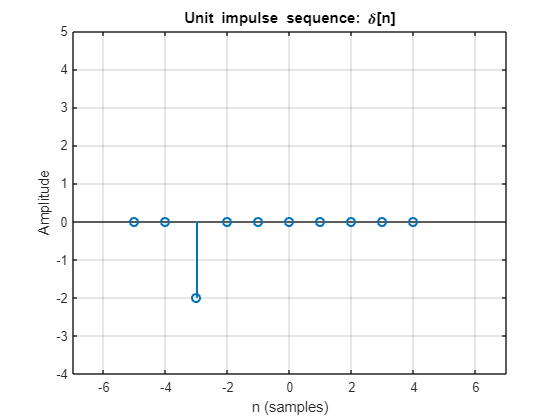

n = -5:4;
unit_impulse= -2*(n==-3);
figure();
stem(n,unit_impulse,'linewidth',1.5)
title('Unit impulse sequence: \delta[n]')
xlabel('n (samples)')
ylabel('Amplitude')
xlim([-7 7])
ylim([-4 5])
grid on

b) ** (0.5 p)  **Plot the each using `xlabel(), ylabel(), xlim(), ylim(), title()` properly. Use `plot()` function. Consider `xlim([-10 10])` for proper visualization.

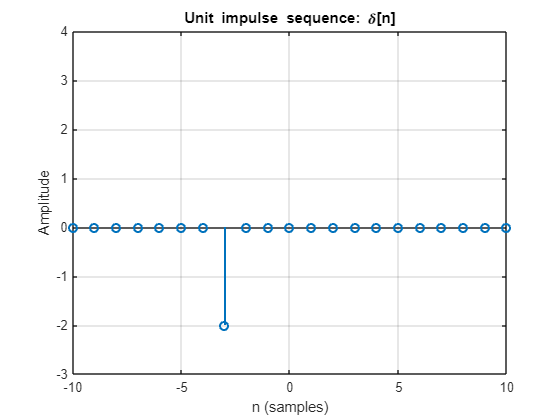

n = -10:10;
unit_imp = -2*(n == -3);
              %? esta preguntando si n es 0, si es 0 es TRUE por lo que va
              %dar 1
% necesitamos definir el unitario
figure;
stem(n,unit_imp, 'Linewidth',1.5)
title('Unit impulse sequence: \delta[n]')
xlabel('n (samples)');
xlim([-10 10]);
ylabel('Amplitude');
ylim([-3 4]);
grid on;

c) ** (0.5 p) **Create a function (user-defined function) that yields a generic unit impulse, defined by:

 
$$x\left\lbrack n\right\rbrack \;=A\cdot \delta \;\left\lbrack n-k\right\rbrack ,\;\;n\in \left\lbrack n_{1\;} ,n_2 \right\rbrack$$
 

Considering the following specifications:

- `INPUTS``:` `n1, n2, k, A`

- `OUTPUTS: ``n, x`

- A prototype is provided:

d) **(1 p) **The set of discret-time signals $\mathit{\mathbf{S}}$, formed by shifted unit impulses is a valid basis for discrete-time signals:


$$\mathit{\mathbf{S}}=\left\lbrace \delta {\;}_k \left\lbrack n\right\rbrack \right\rbrace ,\;\;\;\textrm{where}\;\delta {\;}_k \left\lbrack n\right\rbrack =\delta \left\lbrack n-k\right\rbrack ,\;\;\;\textrm{for}\;\;k\;\in Z\;\;$$


This means that any arbitrary signal $x\left\lbrack n\right\rbrack$ can be expressed as a linear combinations of elements of $\mathit{\mathbf{S}}$ (as a weighted sum of shifted unit impulses). Verify that statement by implementing the following signals:

d.i) **(0.5 p)**

- 
$$\begin{array}{l}
x_1 \left\lbrack n\right\rbrack =\left\lbrace 3,0,-1,2,1,-2\right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\uparrow \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;n=0
\end{array}$$


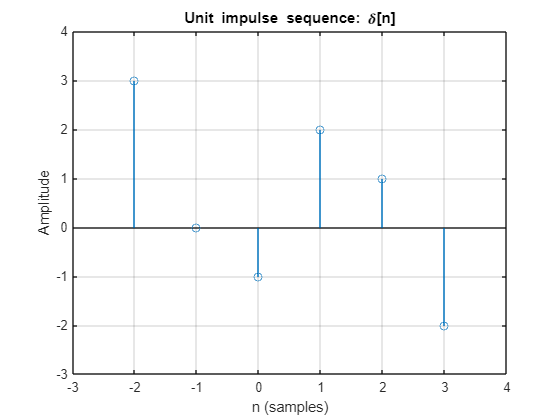

n= -2:3;
unit_impulse = 3*(n==-2) + -1*(n==0) + 2*(n==1)+ 1*(n==2)+ -2*(n==3);
figure();
stem(n,unit_impulse)
title('Unit impulse sequence: \delta[n]')
xlabel('n (samples)');
xlim([-3 4]);
ylabel('Amplitude');
ylim([-3 4]);
grid on;

d.ii) **(0.5 p)**

- 
$$\begin{array}{l}
x_2 \left\lbrack n\right\rbrack =\left\lbrace -1,-3,5,0,1,1\right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\uparrow \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;n=0
\end{array}$$


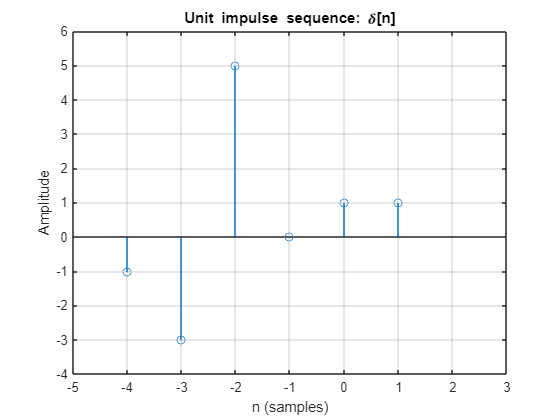

n= -4:1;
unit_impulse = -1*(n==-4) + -3*(n==-3) + 5*(n==-2)+ 1*(n==0)+ 1*(n==1);
figure();
stem(n,unit_impulse)
title('Unit impulse sequence: \delta[n]')
xlabel('n (samples)');
xlim([-5 3]);
ylabel('Amplitude');
ylim([-4 6]);
grid on;

### **QUESTION 3 - Denoising: signal averaging for noise reduction (3.5 p) **

The data provided by a biomedical sensor has been recorded *M* times. Unfortunately, there was some interference in the recording process. The distorted resulting signals are recorded on the file `noisy_data.mat`. Each one of the *M* data-rows corresponds with a single recording of 1s duration (containing *N* samples).

a) **(1 p)** Load the `noisy_data.mat. `Plot  a signal correspnding with the '*k*-th ' recording, where *k* is the last digit of your PUCP code.

**NOTE:**  You must obtain a figure as the shown below by using `xlabel(), ylabel(), xlim(), ylim(), title()` properly.

                                                                                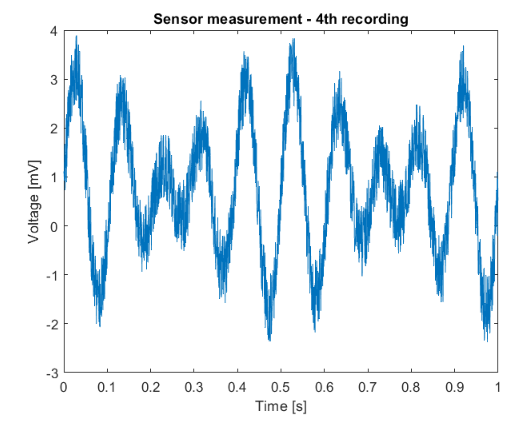

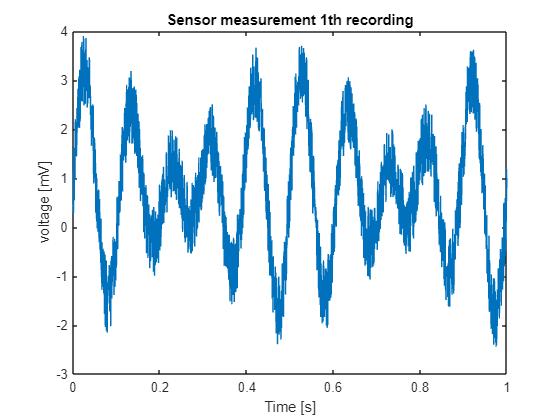

load('noisy_data.mat');
size(noisy_sensor);
x_L= noisy_sensor(1,:);% i only take the first, because my code end in 1
N = size(noisy_sensor,2);
plot(time_vec,x_L) % plot the time vs the recording that i need   
title('Sensor measurement 1th recording')
xlabel('Time [s]')
ylabel('voltage [mV]')
xlim([0 1])
ylim([-3 4])

b)  **(2 p) **In this particular case, it's possible to perform a simple denoising technique based on signal addition (*averaging) *for quality's signal improvement. The associated algorithm is given by:


$$\begin{array}{l}
\overset{-}{x} \left(t\right)=\frac{1}{P}\;\sum_{i=1}^P x_i \left(t\right)\;,\;\;\textrm{where};\\
\overset{-}{x} \left(t\right):\textrm{denoised}\;\textrm{signal}\\
x_i \left(t\right):i-\textrm{th}\;\textrm{signal}\;\left(\textrm{from}\;\textrm{the}\;\textrm{noisy}\;\textrm{set}\right)\\
P:\;\;\;\;#\;\textrm{signals}\;\textrm{considered}\;\textrm{for}\;\textrm{denoising}
\end{array}$$


Perform averaging for denoising the provided signals by considering differente values of *P* . In particular: *P* = {2,4,8,16,32,64,128,256,512}. Plot your results for each value of *P* in a single figure (use `subplot()`)

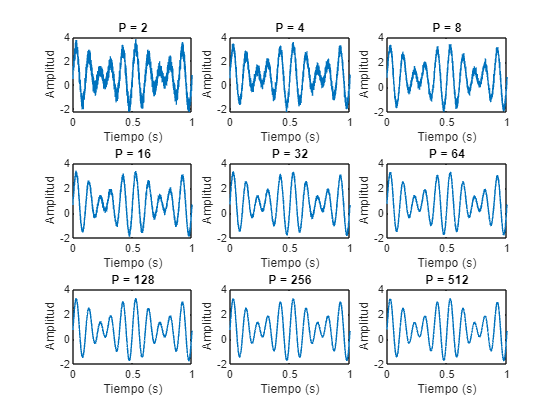

P_valor = [2,4,8,16,32,64,128,256,512];
t = linspace(0, 1, N); % i created a vector ,that goes from 0 to 1, that it is determined by the number of samples
figure();
for i = 1:length(P_valor) %I first made it loop from 1 to the length of P, which is 9 values
    P = P_valor(i); %What I do here is to create a signal of the same original size but all zeros. I assign the variables of P_values to P
    val_sum = zeros(1, N);
    for j= 1: P %hago un for para que j recorra desde 1 hasta la longitud N que es el size con un paso del valor que este en P
        val_sum = val_sum + noisy_sensor(j,:);%sums the recordings starting from j
    end
    val_sum = val_sum ./ P; % the sum is divided by P
    subplot(3, 3, i);% use a 3 x 3 ,because we have 9 values
    plot(t, val_sum);% plot the time with the new val_sum
    xlabel('Tiempo (s)');
    ylabel('Amplitud');
    title(['P = ', num2str(P)]);
end

c) **(0.5 p) **Comment your results:

- What's the effect of increasing the P value? Elaborate an hypthotesis of why this effect is produced.

%The effect observed is that as P increases, the graph becomes clearer and less noisy, as if it were being smoothed out. I believe this occurs because a larger sample is being taken, which means more information is being gathered. Dividing by a larger 
%P provides a more accurate average.

### **QUESTION 4 - Doppler Ultrasound Signal (5 p) **

In the framework of Doppler Ultrasound an ensemble of pulses is transmitted by the ultrasound transducer for acquiring information concerning the internal structures motion.

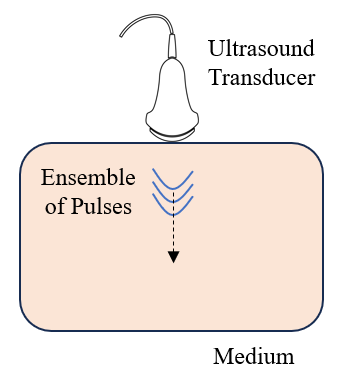

A single pulse can be modeled as the Amplitude Modulation (AM) of a high frequency carrier by using a slow-varying envelope (*modulating signal*) This process can be described mathematically as:

- `Envelope signal:  `$x_{\textrm{env}} =e^{-{\left(\frac{t-t_o }{a}\right)}^2 }$

- `Carrier signal:   `$x_{\textrm{carrier}} =\cos \left(2\pi \ldotp F\ldotp t\right)$

- `AM signal:        `$x_{\textrm{AM}} =x_{\textrm{env}} \ldotp x_{\textrm{carrier}} =e^{-t^2 } \ldotp \cos \left(2\pi \ldotp F\ldotp t\right)$

In this particular case, the carrier is given by a sinusoidal signal and the envelope is given by a Gaussian pulse. 

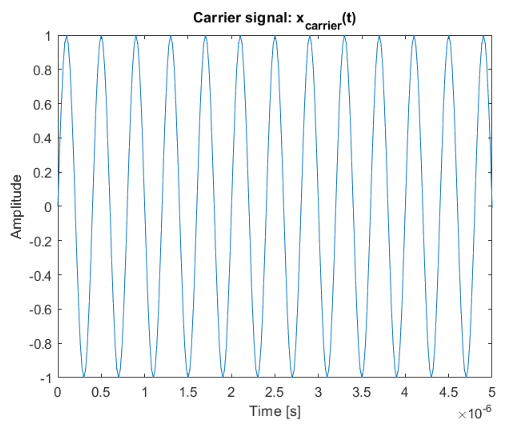    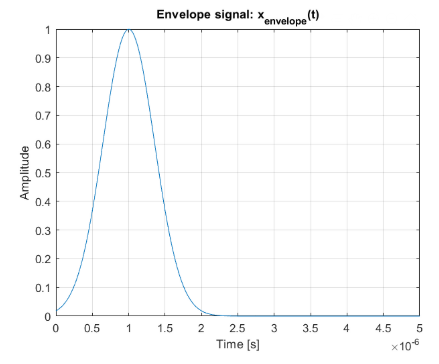  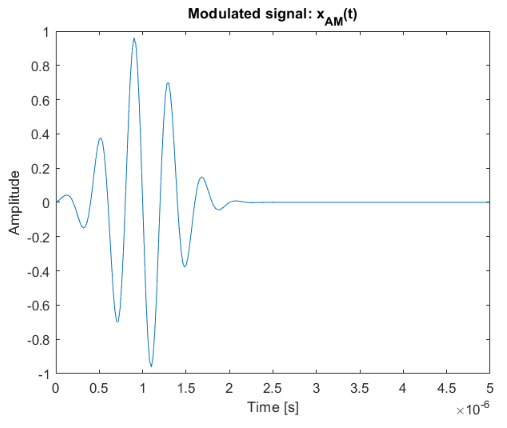

*                                      Fig. 4-a.                                                                     Fig. 4-b                                                                         Fig. 4-c*

a) **(1 p) **Implement and plot the following signals and plot them:

- **(0.5 p)** $x_{\textrm{carrier}} \left(t\right)\;\left(F=2\ldotp 5\;\textrm{MHz}\;\right)$ (*Reference:* *Fig. 4-a.*)

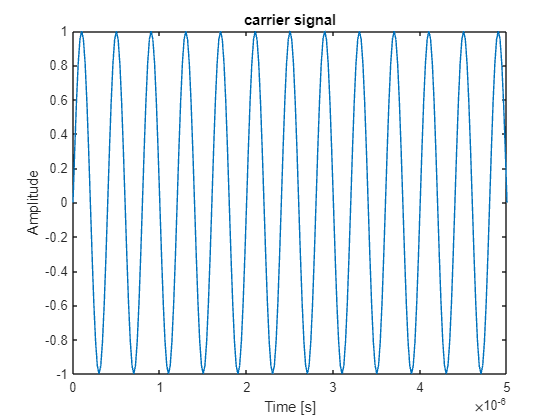

% Carrier Signal
time_resolution =20e-9;
t= 0:time_resolution:2e-4;
xt=  sin(2*pi*t*2.5*10^(6));
figure();
plot(t,xt)
title('carrier signal')
xlabel('Time [s]')
ylabel('Amplitude')
xlim([0 5e-6])
ylim([-1 1])

-  **(0.5 p) **$x_{\textrm{env}} \left(t\right)\;\left(a=0\ldotp 5\cdot {10}^6 ,{\;t}_{o\;} ={10}^{-6} \right)$ (*Reference:* *Fig. 4-b*)

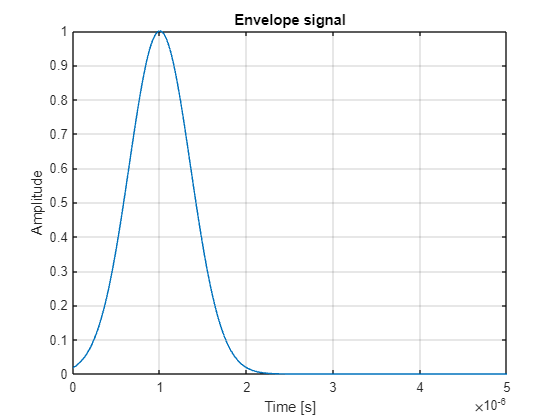

% Envelope Signal
time_resolution =20e-9;
t= 0:time_resolution:2e-4;
a= 0.5e-6;
t0=10^(-6);
xenv=exp(-((t-t0)/a).^2);
figure();
plot(t,xenv)
title('Envelope signal')
xlabel('Time [s]')
ylabel('Amplitude')
xlim([0 5e-6])
ylim([0 1])
grid on

b) **(0.5 p) **Implement the signal $x_{\textrm{AM}} \left(t\right)$ (*modulated signa*l), which corresponds to a single pulse. (*Reference:* *Fig. 4-c*). Plot it.

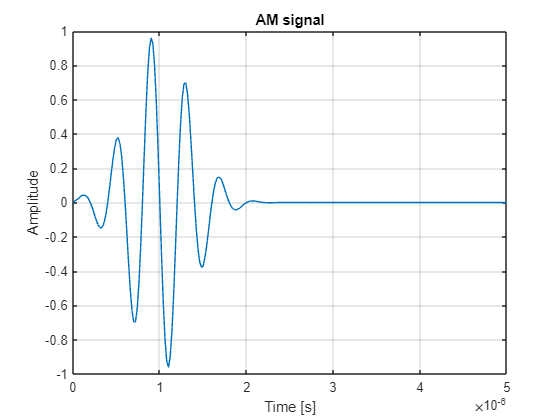

% AM signal
time_resolution =20e-9;
t= 0:time_resolution:2e-4;
xmod=xenv.*xt;
figure();
plot(t,xmod)
title('AM signal')
xlabel('Time [s]')
ylabel('Amplitude')
xlim([0 5e-6])
ylim([-1 1])
grid on

c)** (2 p) **The desired ensemble signal $x_{\textrm{ensemble}} \left(t\right)$is shown in the image below (*Fig. 4-e*):

      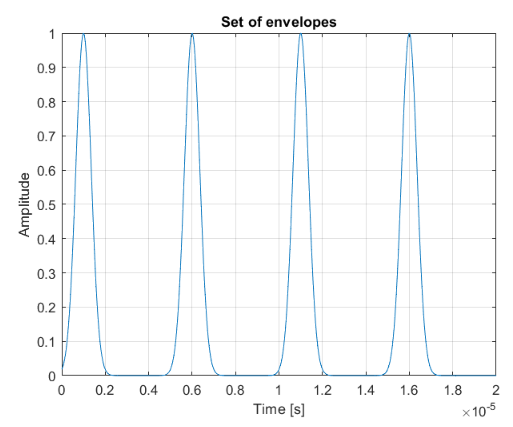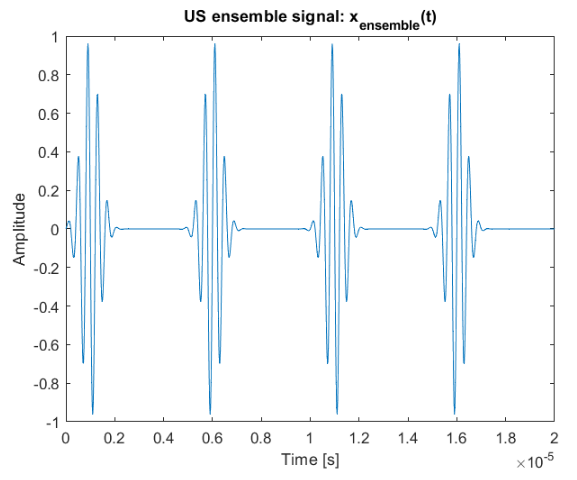

                                                 *Fig. 4-d*                                                                                               *Fig. 4-e*

It has the following characteristics:

- #pulses/ensemble = 4

- First pulse is centered at $t=1\;\textrm{us}$  

- Time invertal between pulses: $T_{\textrm{pulse}} =5\;\textrm{us}$

c.1) **(1 p) **Implement and plot the signal shown in *Fig. 4-d *by taking as the basic building block the signal $x_{\textrm{AM}} \left(t\right)$. Use `grid on `to have a visual guidance for the center of each individual envelope.

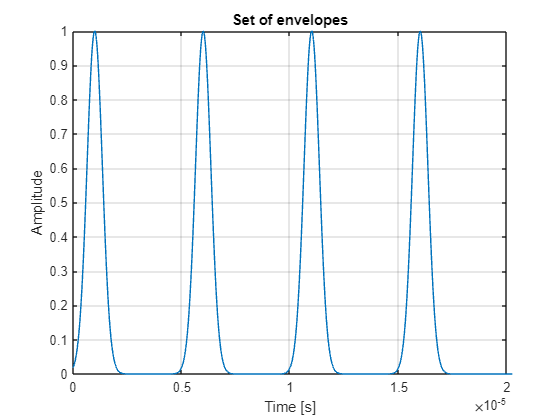


time_resolution =20e-9;
t= 0:time_resolution:2e-4;
a= 0.5e-6;
pulse= 4;
xset_ev= zeros(size(t));
pulse_center =[0.1e-5 0.6e-5 1.1e-5 1.6e-5]; %there the place of the pulse cente
for i = 1:pulse
    valor = exp(-((t-pulse_center(i))/a).^2);% so i are gonna start to count from 1 to the last pulse
    %so i rest the t and the pluse center.
    xset_ev = xset_ev + valor;% and i add this value to the array
end

figure();
plot(t,xset_ev)
title('Set of envelopes')
xlabel('Time [s]')
ylabel('Amplitude')
xlim([0 2e-5])
ylim([0 1])
grid on

c.2) **(1 p) **Implement and plot the signal shown in *Fig. 4-e *from the previously implemented signal (item c.1)

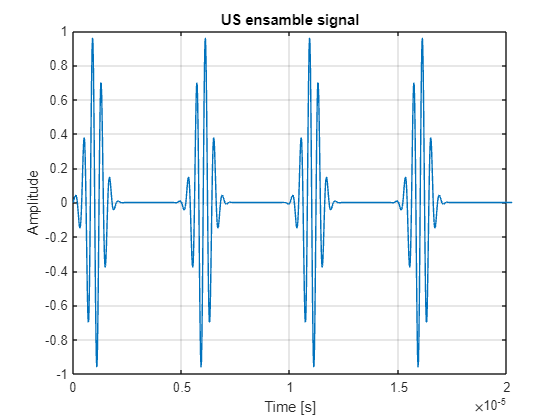

x_Am= xset_ev.*xt;% i only multiplicate, because i got the set of envelopes and the carrier signal
figure();
plot(t,x_Am)
title('US ensamble signal')
xlabel('Time [s]')
ylabel('Amplitude')
xlim([0 2e-5])
ylim([-1 1])
grid on

d) **(1.5 p) **It is requested to generate two consecutive ensembles as is shown in the figure below:

           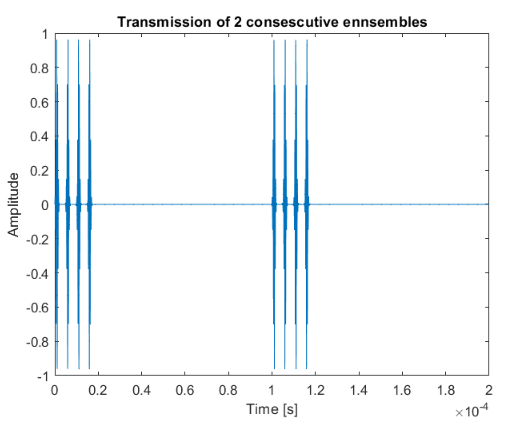

*                                                               Fig. 4-f*

Implement the given signal by considering the information below:

- Pulse Repetition Frequency: $\textrm{PRF}=10\;\textrm{kHz}$ 

                ($\Delta t=\frac{1}{\textrm{PRF}}$   gives the time-interval between consecutive ensembles)

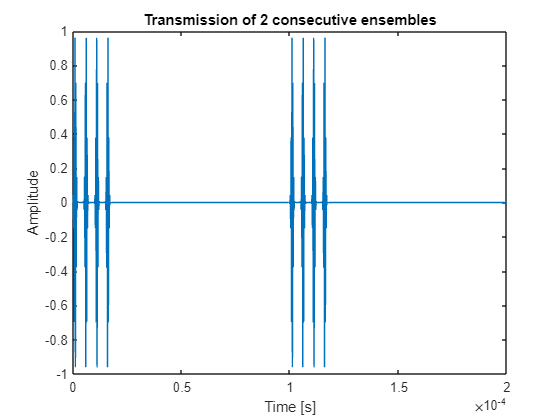

PRF = 10e3;
t_delta= 1/ PRF;% i did this because a i needed to know the new consecutice
t_nuevo= time_resolution/t_delta; %this is to know the knew time
funcion1=(sin(2*pi*2.5*10^(6)*t).*(exp(-((t-t0)/a).^2)+exp(-(((t-(5e-6)-t0)/a).^2))+exp(-(((t-(10e-6)-t0)/a).^2))+exp(-(((t-(15e-6)-t0)/a).^2))));
%this is the ensamble found in the last incise, but we add the t_delta
%because is the new interval
% we did that because y add the another signal that is consecutive with the
% first, so i only add the new_time to the old time so i got the place
% of the second signal 
funcion2=(sin(2*pi*2.5*10^(6)*(t-t_delta)).*(exp(-((t-t0-t_delta)/a).^2)+exp(-(((t-t_delta-(5e-6)-t0)/a).^2))+exp(-(((t-t_delta-(10e-6)-t0)/a).^2))+exp(-(((t-t_delta-(15e-6)-t0)/a).^2))));
sum_tiem_nuevo= funcion1 + funcion2;
figure;
plot(t,sum_tiem_nuevo);
xlim([0 2e-4]);
ylim([-1 1])
xlabel('Time [s]')
ylabel('Amplitude')
title('Transmission of 2 consecutive ensembles')

### **QUESTION 5 - Discrete-Time Systems Properties (6 p) **

A discrete-time system $T$ process an input signal $x\left\lbrack n\right\rbrack$and yields an output signal $y\left\lbrack n\right\rbrack$

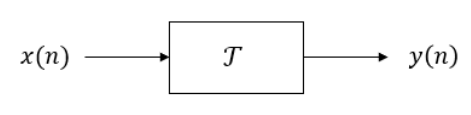

If a discrete-time system posses a property (Linearity, Time-Invariance, Causality, BIBO Stability), it means that it holds for any arbitrary input-signal. It's possible to apply the following test for interrogating Linearity and Time-Invariance properties:

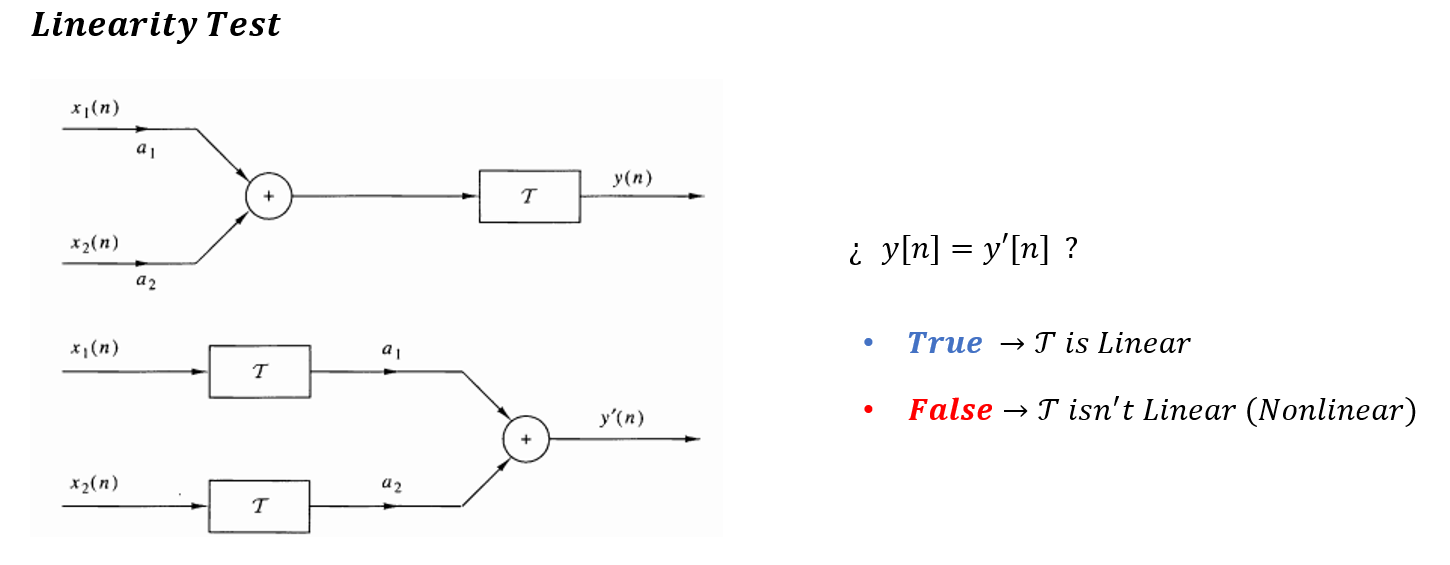

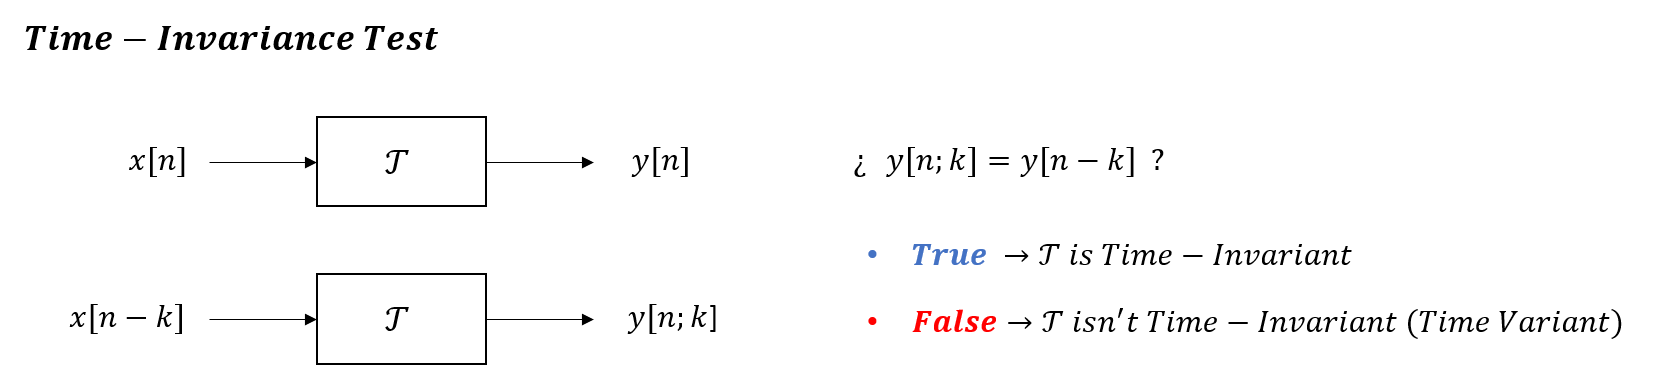

a) **(1 p)** Evaluate analitically if the provided systems satisfy the following properties:

- Linearity

- Time-Invariance

a.i) **(0.5 p)** $y\left\lbrack n\right\rbrack =T_1 \left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =\frac{x\left\lbrack n+10\right\rbrack +x\left\lbrack n-10\right\rbrack }{2\;}$

- Linearity


$$\begin{array}{l}
T_1 \left\lbrace x_1 \left\lbrack n\right\rbrack \right\rbrace \;=y_1 \left\lbrack n\right\rbrack \;=\\
T_1 \left\lbrace x_2 \left\lbrack n\right\rbrack \right\rbrace \;=y_2 \left\lbrack n\right\rbrack \;=\\
\\
x\left\lbrack n\right\rbrack =a_1 \ldotp x_1 \left\lbrack n\right\rbrack +a_2 \ldotp x_2 \left\lbrack n\right\rbrack \\
T_1 \left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =T_2 \left\lbrace a_1 \ldotp x_1 \left\lbrack n\right\rbrack +a_2 \ldotp x_2 \left\lbrack n\right\rbrack \right\rbrace =\;\\
\\
\textquestiondown \;T_1 \left\lbrace a_1 \ldotp x_1 \left\lbrack n\right\rbrack +a_2 \ldotp x_2 \left\lbrack n\right\rbrack \right\rbrace \;=={a_1 \ldotp T}_1 \left\lbrace x_1 \left\lbrack n\right\rbrack \right\rbrace +{a_2 \ldotp T}_1 \left\lbrace x_2 \left\lbrack n\right\rbrack \right\rbrace ?\;\;\to T\;|\;F\\
T_1 \;\;\textrm{is}|{\textrm{isn}}^{\prime } t\;\textrm{Linear}\;
\end{array}$$


- Time Invariance


$$\begin{array}{l}
T_1 \left\lbrace x\left\lbrack n\right\rbrack \right\rbrace \;=\;y\left\lbrack n\right\rbrack \;=\;\;\to \;\;y\left\lbrack n-k\right\rbrack =\;\\
T_1 \left\lbrace x\left\lbrack n-k\right\rbrack \right\rbrace =y\left\lbrack n;k\right\rbrack =\\
\\
\textquestiondown \;y\left\lbrack n;k\right\rbrack \;==y\left\lbrack n-k\right\rbrack \;?\;\;\;\to \;\;\;\textquestiondown \;n\ldotp x\left\lbrack n-k\right\rbrack \;==\;\left(n-k\right)\ldotp x\left\lbrack n-k\right\rbrack \;?\;\;\to \;\;\;T\;|\;F\\
\\
T_1 \;{\textrm{is}|\textrm{isn}}^{\prime } t\;\textrm{Time}-\textrm{Invariant}\ldotp 
\end{array}$$


% ¿Linear or Nonlinear?
% Is linear, because when i do a superposition its works.
% (x3 [n+10]+ x3[n-10])/2 =(x1 [n+10]+ x1[n-10])/2 + (x2 [n+10]+ x2[n-10])/2
% we know that x3[n] = x1[n] + x2[n]
%so  ((x1+x2)[n+10] + (x1+x2)[n-10])/2  x1[n+10]+x2[n+10] +x1[n-10]+x2[n-10]
% so this can write like this: x1[n+10] +x1[n-10] /2 + x2[n-10] + x2[n-10]/2
%this is the same to first equation that I show, so is linear.

% ¿Time-Invariant or Time-Variant?
%is Time -Invariant, now a give a example
% if we move x[n-5]
% so the equation change
% x[n+10-5] + [x-10-5]/" --> x[n+5] + x[n-15]/2 = y[n+5] + y[n-15]/2
% son invariante en el tiempo

a.ii) **(0.25 p)**$\;y\left\lbrack n\right\rbrack =T_2 \left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =n\ldotp x\left\lbrack n\right\rbrack$

- Linearity


$$\begin{array}{l}
\mathrm{y1}\left\lbrack n\right\rbrack =\mathrm{n1}\ldotp \mathrm{x1}\left\lbrack n\right\rbrack \\
\left.\mathrm{y2}\left\lbrack n\right\rbrack \right\rbrack =\mathrm{n2}\ldotp x\;\left\lbrack n\right\rbrack \\
x\left\lbrack n\right\rbrack =\mathrm{a1}\ldotp \mathrm{x1}\left\lbrack n\right\rbrack +\mathrm{a2}\ldotp \mathrm{x2}\left\lbrack n\right\rbrack \\
\mathrm{T2}\left\lbrace \left\lbrack \mathrm{a1}\ldotp \mathrm{x1}\left\lbrack n\right\rbrack +\mathrm{a2}\ldotp \mathrm{x2}\left\lbrack n\right\rbrack \right\rbrack \right\rbrace =n\ldotp \mathrm{a1}\ldotp \mathrm{x1}\left\lbrack n\right\rbrack +n\ldotp \mathrm{a2}\ldotp \mathrm{x2}\left\lbrack n\right\rbrack \\
\mathrm{a1}\ldotp \mathrm{T1}\left\lbrace \mathrm{x1}\left\lbrack n\right\rbrack \right\rbrace +\mathrm{a2}\ldotp \mathrm{T2}\left\lbrace \left\lbrack \mathrm{x2}\left\lbrack n\right\rbrack \right\rbrack \right\rbrace =\mathrm{a1}\ldotp n\ldotp \mathrm{x1}\left\lbrack n\right\rbrack +\mathrm{a2}\left(\ldotp n\ldotp \mathrm{x2}\left\lbrack n\right\rbrack \right.\\
\mathrm{there}\;\mathrm{are}\;\mathrm{equal},\mathrm{is}\;\mathrm{Linear}
\end{array}$$


- Time Invariance


$$\begin{array}{l}
\mathrm{T2}\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =y\left\lbrack n\right\rbrack \;\mathrm{so}\;y\left\lbrack n-k\right\rbrack =\left(n-k\right)\ldotp x\left\lbrack n-k\right\rbrack \\
\mathrm{T2}\left\lbrace x\left\lbrack n-k\right\rbrack \right\rbrace =n\ldotp x\left\lbrack n-k\right\rbrack \;,\mathrm{there}\;\mathrm{are}\;\mathrm{differet}\;F
\end{array}$$


% ¿Linear or Nonlinear?
%Is linear
% ¿Time-Invariant or Time-Variant?
%Not time ivariant

a.iii) **(0.25 p)** $y\left\lbrack n\right\rbrack =T_3 \left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =n{\ldotp x}^2 \left\lbrack n\right\rbrack$

- Linearity


$$$$


- Time Invariance


$$$$


% ¿Linear or Nonlinear?
%Is Linear
% ¿Time-Invariant or Time-Variant?
%Not time- Variant

b) **(5 p)** Verify your results by considering the following test input signals $x_1 \left\lbrack n\right\rbrack$ and $x_2 \left\lbrack n\right\rbrack$: 

b.i) **(0.5 p)** Implement and plot them. Consider `xlim([-100 100])` for your plots.

- 
$$x_1 \left\lbrack n\right\rbrack =\cos \left(\frac{\pi \;}{40}n\right),\;\;n\in \left\lbrack -200,199\right\rbrack \;$$


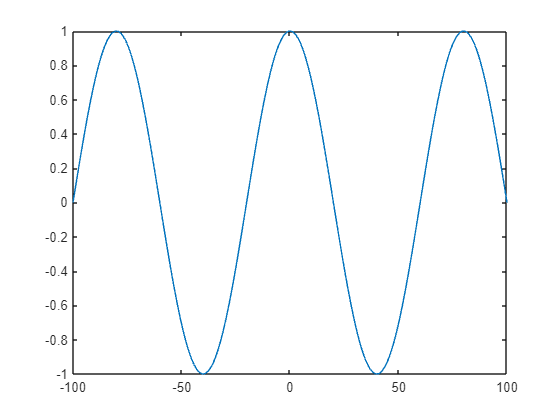

n= -200:199;
x_1 = cos((pi/40)*n);
figure();
plot(n,x_1);
xlim([-100 100])

- 
$$x_2 \left\lbrack n\right\rbrack =\cos \left(\frac{\pi \;}{50}n\right),\;\;n\in \left\lbrack -200,199\right\rbrack$$


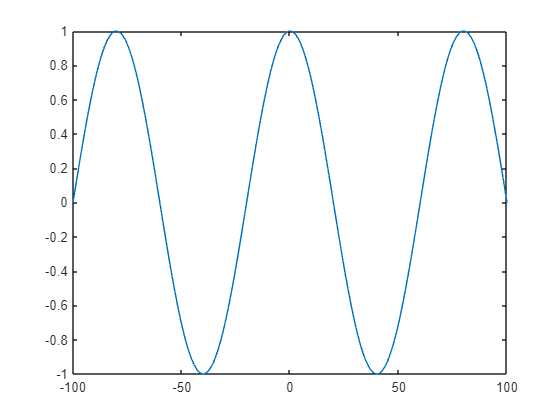

n= -200:199;
x_2 = cos((pi/50)*n);
figure();
plot(n,x_2);
xlim([-100 100])

b.2) **(4.5 p)** In order to experimentally validate linearity and time-invariance properties for each system, you must perform the Linearity and Time-Invariance tests and use the provided signals $x_1 \left\lbrack n\right\rbrack$ and $x_2 \left\lbrack n\right\rbrack$. Consider the specified parameters for testing:

- Linearity $\left.{\left(a\right.}_1 =1,a_2 =1\right),\textrm{where}\;a_1 \;\textrm{and}\;a_2 \;\textrm{are}\;\textrm{the}\;\textrm{weights}\;\textrm{for}\;\textrm{the}\;\textrm{input}\;\textrm{signals}\;\textrm{used}\;\textrm{in}\;\textrm{Linearity}\;\textrm{test}$

- Time-Invariance $k=20,,\textrm{where}\;k\;\textrm{is}\;\textrm{the}\;\textrm{delay}\;\textrm{for}\;\textrm{the}\;\textrm{Time}-\textrm{Invariance}\;\textrm{test}$ 

You must implement the required code for testing and show similar figures as provided below for graphical validation of your results (use `subplot()`). Customize your subplots by setting `xlabel(), ylabel(), xlim(), ylim(), title() `properly.

**(1.5 p) SYSTEM TEST 1** 

i) $y\left\lbrack n\right\rbrack =T_1 \left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =\frac{x\left\lbrack n+10\right\rbrack +x\left\lbrack n-10\right\rbrack }{2\;}$

- Linearity

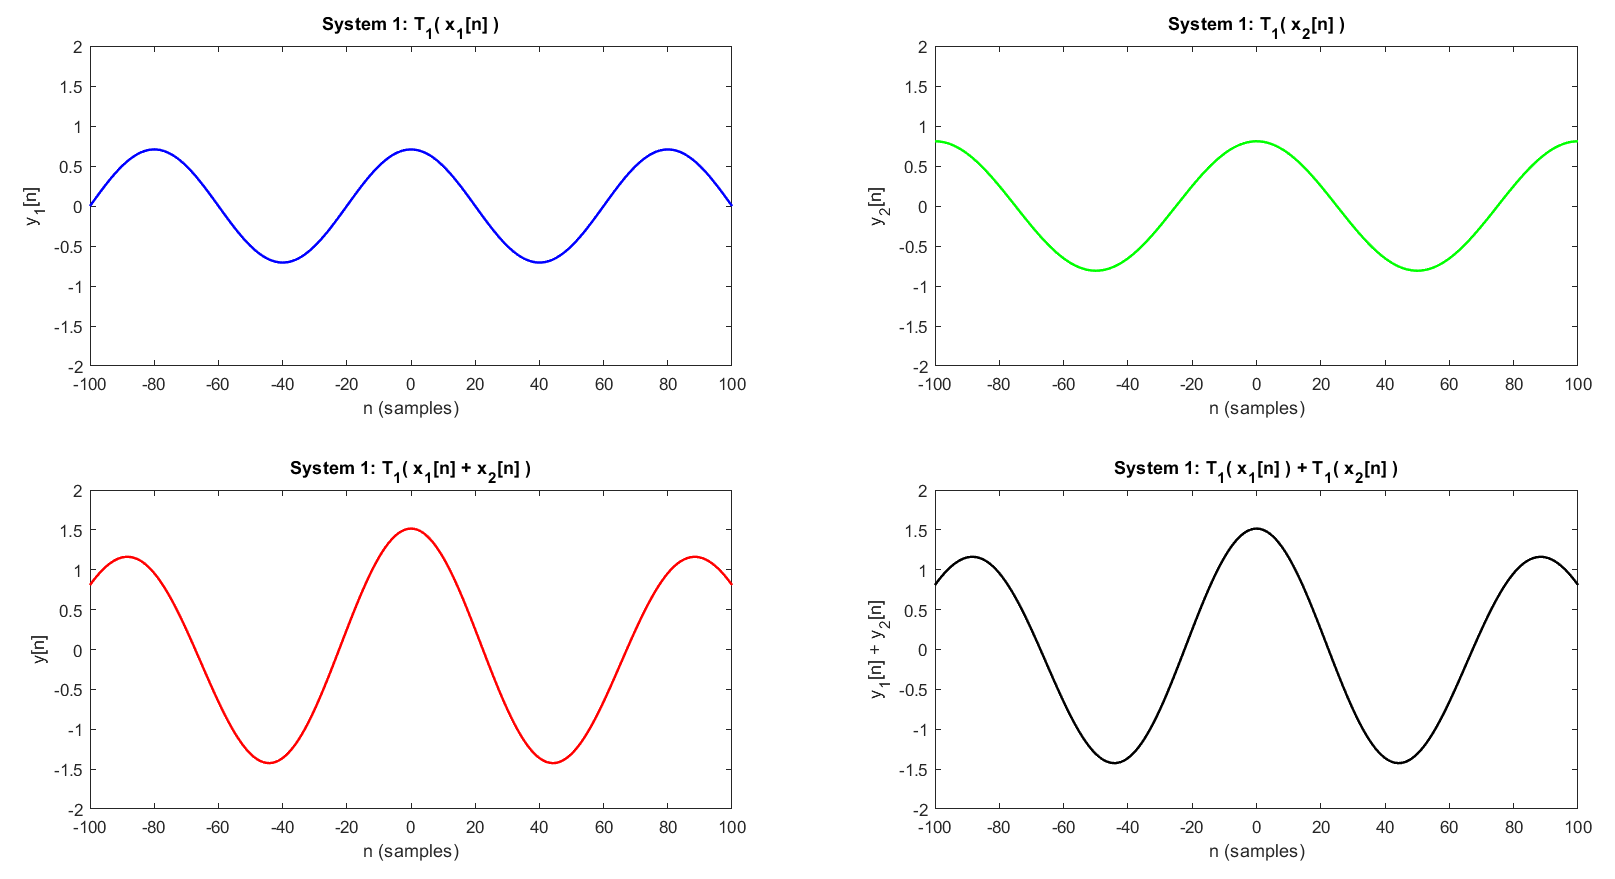

- Time invariance

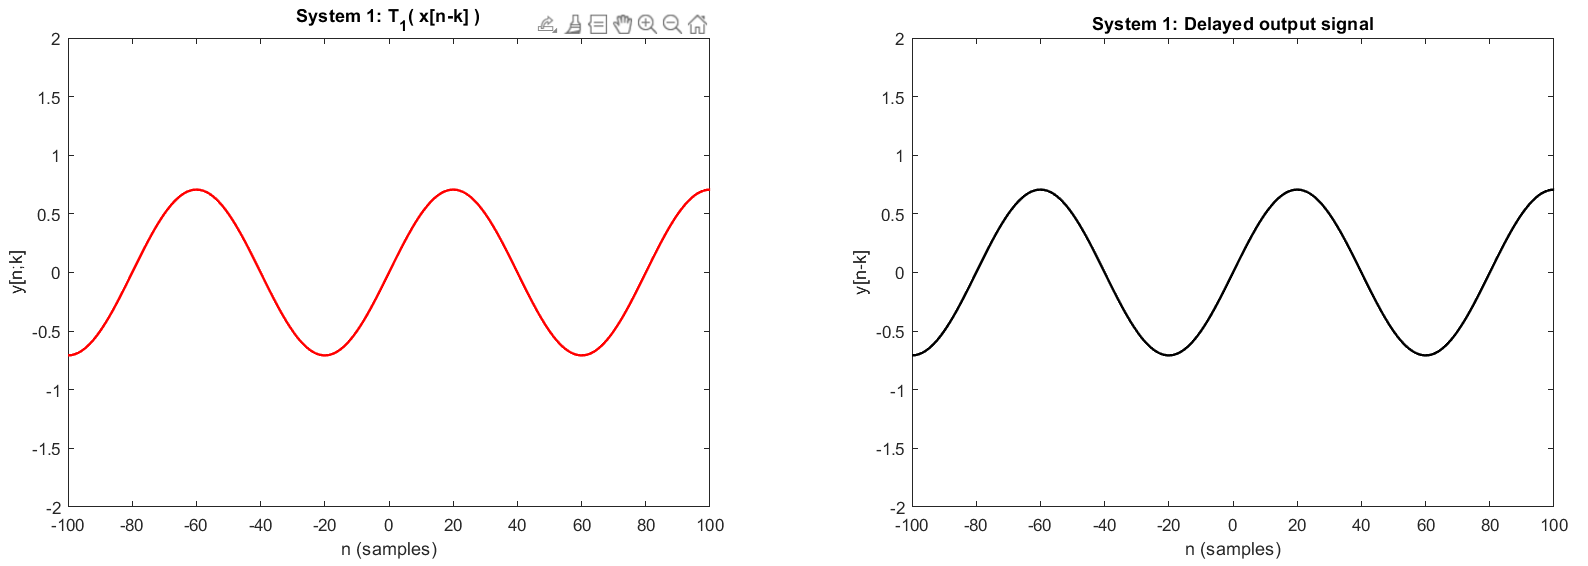

**(1.5 p) SYSTEM TEST 2** 

i) $y\left\lbrack n\right\rbrack =T_2 \left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =n\ldotp x\left\lbrack n\right\rbrack$

- Linearity

- Time invariance

**(1.5 p) SYSTEM TEST 3** 

i) $y\left\lbrack n\right\rbrack =T_3 \left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =n\ldotp x^2 \left\lbrack n\right\rbrack$

- Linearity

- Time invariance

function [x,n] = unitimp_sig(n1,n2,k,A)

% unitimp_sig ---> Creates a generic unit impulse respone

%----------
% INPUTS
%----------
% n1: start index
% n2: end index
% k: shifting factor
% A: scaling factor (amplitude)

%----------
% OUTPUTS
%----------
% x: scaled and shifted Unit Impulse
% n: indices vector
n = n1:n2
x = A*(n==k)
end